## Questão 2

4-QAM (BPSK), probabilidade de erro de bit (Pb)

a) natural (00, 01, 10, 11)

b) Gray (00, 01, 11, 10)

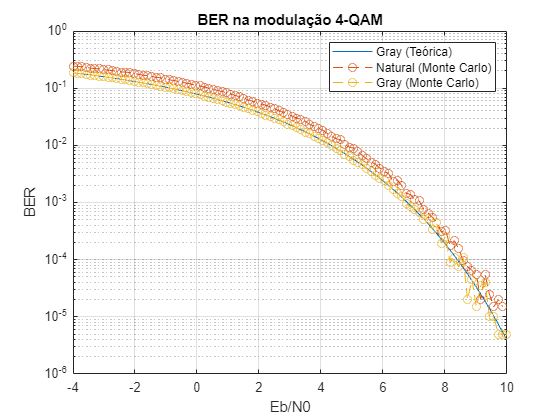

rng('default')
eb_n0_dB = linspace(-4,10,100);
eb_n0 = 10.^(eb_n0_dB./10);

[Pb_teorica, ~] = berawgn(eb_n0_dB, 'qam', 4); % Pb
Pb_montecarlo_natural = qam_4_natural(eb_n0);
Pb_montecarlo_gray = qam_4_gray(eb_n0);

figure();
semilogy(eb_n0_dB, Pb_teorica); hold on;
semilogy(eb_n0_dB, Pb_montecarlo_natural, 'LineStyle', '--', 'Marker', 'o');
semilogy(eb_n0_dB, Pb_montecarlo_gray, 'LineStyle', '--', 'Marker', 'o'); hold off;

xlabel('Eb/N0');
ylabel('BER');
legend('Gray (Teórica)', 'Natural (Monte Carlo)', 'Gray (Monte Carlo)');
title('BER na modulação 4-QAM');
grid on